# Bildkompression

Dieses Programm zeigt eine Anwendung der Singulärwertzerlegung in der Bildkompression.

Als Ausgangsbild wird eine Aufnahme des Nummernschilds vom PKW von Gene Golub (1932-2007), einem der  bedeutendsten Numeriker  auf dem Gebiet der Numerischen Linearen Algebra, verwendet. Die Dimension der Pixelmatrix ist  450x600. Das Bild wird eingelesen und gezeigt: 

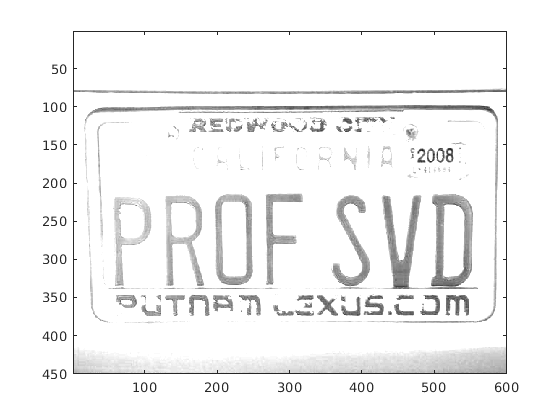

A=double(imread('https://www.igpm.rwth-aachen.de/Download/DahmenReusken/Golub.jpg'));
[m,n]=size(A);
image(A); 
colormap('gray');

Die Singulärwertzerlegung der Matrix $A$ wird berechnet und die Singulärwerte werden geplottet.

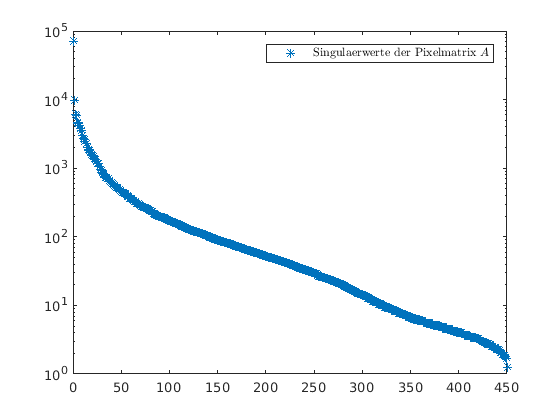

[U,S,V]=svd(A);
semilogy((1:450),diag(S),'*');
leg1=legend('Singulaerwerte der Pixelmatrix $A$');
 set(leg1,'Interpreter','latex');

Mittels des Parameters $k$ wird eine beste Rang-$k$-Approximation $A_k$ der Matrix $A$ bestimmt

k=10

k = 10

Das entsprechende komprimierte Bild wird gezeigt.

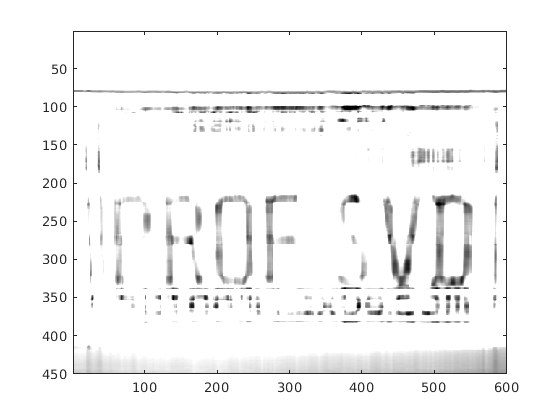

Sk=S(1:k,1:k);
Uk=U(:,1:k);
Vk=V(:,1:k);
Ak=Uk*Sk*Vk';
image(Ak);

Der relative Approximationsfehler err:=$\|A-A_k\|_2/\|A\|_2$ beträgt

Fehler=S(k+1,k+1)/S(1,1)

Fehler = 0.0393

Der Kompressionsfaktor beträgt

Kompressionsfaktor=(m*n)/(m*k+n*k+k*k)

Kompressionsfaktor = 25.4717

# Aktivität

Variieren Sie den $k$-Wert und schauen Sie sich das entsprechende komprimierte Bild an.